PHYSICS 434 

LAB 6 

Jeff Jiang

Lab Partners: Thomas Conaway, Avi Soval

Hour on the lab : 10

## Confidence intervals

First, I create the background that is a Poisson background with mean 100 and 5000 data points in order to simulate LHC data.

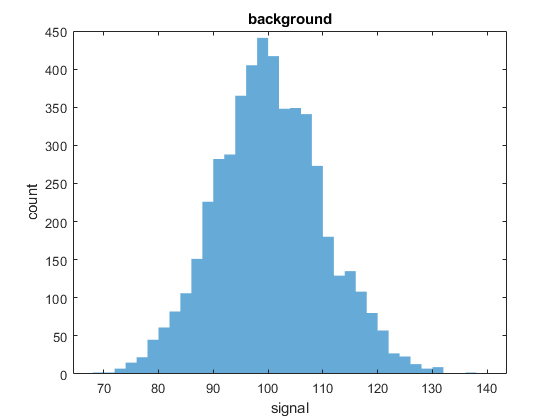

clc; clear; close all;
PoissonMean100 = makedist('Poisson',"lambda",100);
BackgroundData = random(PoissonMean100,[1 5000]);
figure;
histogram(BackgroundData,"EdgeColor","none");
title('background');
xlabel('signal')
ylabel('count')

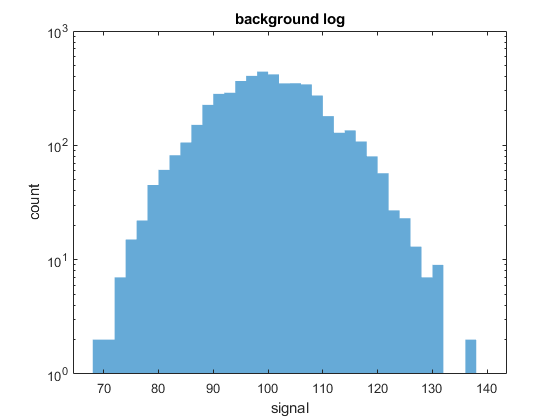

figure;
histogram(BackgroundData,"EdgeColor","none");
set(gca,'YScale',"log");
title('background log');
xlabel('signal')
ylabel('count')

**Problem 1**

The first problem is to check the background distribution and determine where the 5σ sensitivity threshold is. 

From Z table we know the Probability for 5 sigma is 2.8571e-7. We use inverse cumulative of Poisson distribution function to find the thresh hold for 5 sigma. We get the thresh hold at 154.

Prob5Sigma = 2.8571e-7

Prob5Sigma = 2.8571e-07


Thresh5Sigma = icdf(PoissonMean100,1-Prob5Sigma)

Thresh5Sigma = 154

**Problem 2**

We simulated a set of injected signals of a *single strength*. I make my simulated signal around 8 sigma (190). I inject this signal into the background data 1000 times.

Prob8Sigma = 6.22096e-16

Prob8Sigma = 6.2210e-16

Thresh8Sigma = icdf(PoissonMean100,1-Prob8Sigma)

Thresh8Sigma = 190

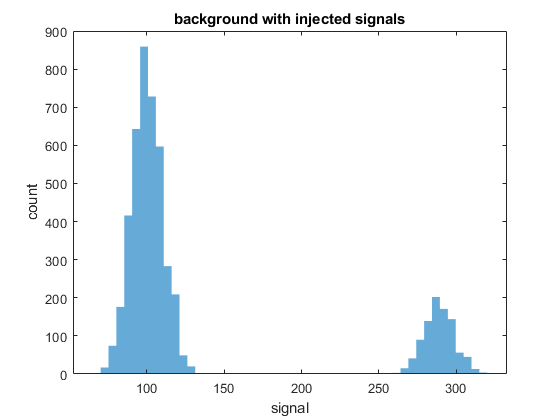

size = 5000;
Signal = zeros(1,size);
Signal(randi(numel(Signal),[1,1000])) = 190;
Obssiganl = BackgroundData + Signal;
figure;
histogram(Obssiganl,50,"EdgeColor","none")
title('background with injected signals');
xlabel('signal')
ylabel('count')

The background with injected signals is show above. The mean for the background is centered at 100. The mean for the observed signals is centered at 290. The background looks like a Poisson distribution. The observed signal is somewhat symmetric due to the big data set I injected.

My observed signal is biased since the signal I observed is distributed around 290. Which did not matches the 8 sigma(190) that I injected. I think the observed signals is greater than the injected signal due to the effect of the background signal. The observed value is stronger than the true injected signal.

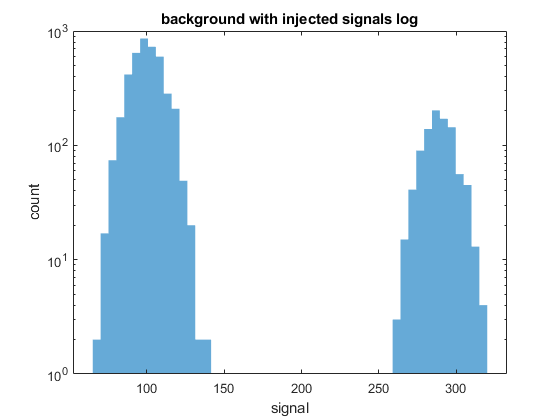

figure;
histogram(Obssiganl,50,"EdgeColor","none");
set(gca,'YScale',"log");
title('background with injected signals log');
xlabel('signal')
ylabel('count')

**Problem 3**

Next, I made a suite of injected signals. I created a range of injected signal strengths, starting at zero and extending well above 8 sigma(190). The range of injected signal strengths go from 0 to 500 which is will above 8 sigma. For each signal strengths I created 1000 signals to inject.  

BackgroundData2 = random(PoissonMean100,[1000 1000]);
Signalstrength = linspace(0,500,1000);
[scratch, Signal2] = meshgrid(Signalstrength);
Obssignal2 = BackgroundData2 + Signal2

Obssignal2 =   104.0000   99.0000  109.0000  108.0000  103.0000  110.0000  109.0000   94.0000  116.0000  106.0000  103.0000   77.0000   87.0000  101.0000   86.0000   96.0000  111.0000  115.0000  106.0000  111.0000   94.0000   95.0000   85.0000  116.0000  120.0000   90.0000   85.0000   95.0000  110.0000  107.0000  102.0000  114.0000   88.0000  116.0000   91.0000  102.0000  102.0000   84.0000  103.0000   97.0000   97.0000  121.0000   97.0000  104.0000   70.0000  104.0000  100.0000   99.0000  105.0000  104.0000
   92.5005   97.5005  116.5005  108.5005  103.5005  105.5005   78.5005   88.5005   93.5005  105.5005   90.5005  107.5005  118.5005  104.5005   99.5005  112.5005   90.5005  130.5005  120.5005  109.5005  114.5005   90.5005  115.5005   87.5005  101.5005   94.5005   95.5005  112.5005  108.5005  111.5005   96.5005   89.5005   76.5005   83.5005  103.5005   98.5005   95.5005   89.5005  102.5005  101.5005   98.5005   98.5005   97.5005   93.5005  101.5005  107.5005  100.5005  100.5005   92.

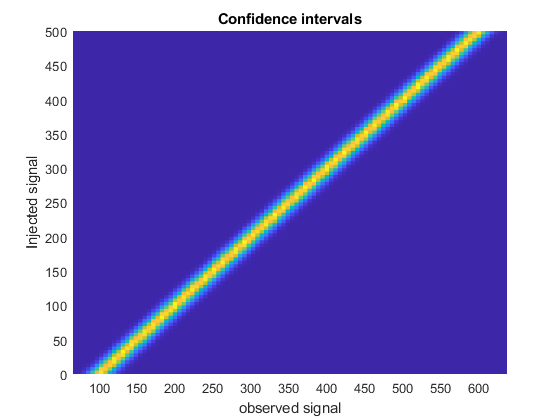

figure;
histogram2(Obssignal2,Signal2,100,'DisplayStyle','tile','ShowEmptyBins','on');
ylabel("Injected signal");
xlabel("observed signal");
title("Confidence intervals");

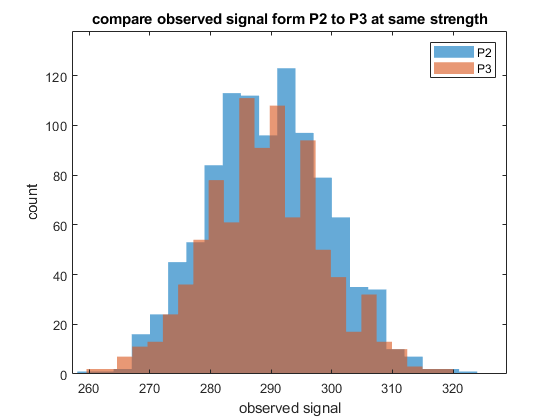

figure;
histogram(Obssignal2(380,:),'EdgeColor',"none");
hold on
histogram(Obssiganl,100,"EdgeColor","none");
xlim([257.3 328.9]);
ylim([0 138]);
ylabel("count");
xlabel("observed signal");
title("compare observed signal form P2 to P3 at same strength");
legend('P2', 'P3');

The observed signal from P2 and P3 looks similar when the injected signal is around 8 sigma(190). They both have mean signal around 290. The P3 observed signal is bias too since the signal I checked was injected around 190 but the signal I observed is around 290. 

This is most likely due to the background having a strong effect on the true signals that we are interjecting. I think the observed signals is greater than the injected signal due to the effect of the background signal.

I selected an observed signal 290 and created a 1D histogram of the injected signal pdf().

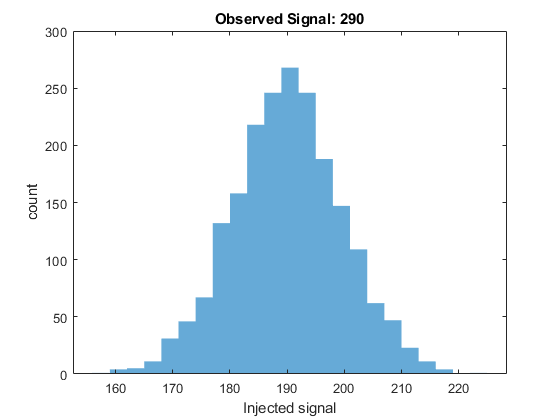

Injected = Signal2(abs(290-Obssignal2)<0.5);
figure;
histogram(Injected,"EdgeColor","none");
title("Observed Signal: 290");
xlabel("Injected signal");
ylabel("count");

When the observed signal is 290 the distributed injected signal is around 190. 

For my observed signal 290, the 1σ uncertainty on the true signal strength are the bounds around the true signal that contain 66% of the data. Which is 33% above the mean and the 33% below the mean. They will give me the upper and lower bounds of probability.

Probability = fitdist(Injected,"Poisson");
Lambda = poissfit(Injected);
Pmean = cdf(Probability,Lambda);
Center = icdf(Probability,Pmean);
LowerBound = icdf(Probability,Pmean-0.33);
UpBound=icdf(Probability,Pmean+0.33);
disp(Center + " (+" + (UpBound-Center) + "|-" + (Center-LowerBound) + ")");

189 (+14|-13)


From calculation above the injected signal are not symmetric because different in the upper bound and lower bound of the one sigma probability are not the same. I think it make sense because the signal is randomly injected to the background noise, so it is unlikely to get the symmetric distribution. 

**Problem 4**

Using the same setup as in problem 3, I picked a relatively weak signal one sigma. Which has thresh hold around 110.

Prob1Sigma = 1.58655e-1

Prob1Sigma = 0.1587

Thresh1Sigma = icdf(PoissonMean100,1-Prob1Sigma)

Thresh1Sigma = 110

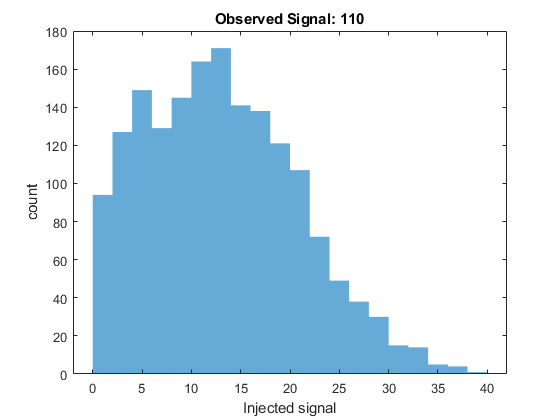

Injected2 = Signal2(abs(110-Obssignal2)<0.5);
figure;
histogram(Injected2,"EdgeColor","none");
title("Observed Signal: 110");
xlabel("Injected signal");
ylabel("count");

With The observed signal around 110 the pdf() extends to zero.

If the true signal pdf() extend to zero, it can mean that there is a possibility for the background signal to match the observation signal.

For calculate a 95% confidence upper bound. I used many different way. 

In order to find the upper bound I made the pdf() normalized. 

The statistical question is: if I observe this candidate signal (and it is too weak to claim a detection), then the true signal would be less than *X* 95% of the time.

Below is the method for my partner used to find the upper bound. His method integrating to histogram in a for loop and find the upper bound.

Binedges = min(Injected2)-0.5:max(Injected2)+0.5;
p2 = histcounts(Injected2,Binedges,'Normalization','pdf');
sumup2 = 0;
for k = 1:numel(p2)
    sumup2 = sumup2 + p2(k);
    if sumup2 > 0.95
        break;
    end
end
upperconf = Binedges(k) + 0.5

upperconf = 27

Below is the method I used to find the upper bound. I created a normal fit for the histogram and used inverse cumulative distribution function to find the upper bound and round the number up to get a whole number. 

Probability2 = fitdist(Injected2,"Normal");
Lambda2 = normfit(Injected2);
UpperBound2 = ceil(icdf(Probability2,0.95))

UpBound2 = 26

At the end the both way will give the similar result.